%Create a .mat file for saving data
foldernam = "Evolution - Praful\"

foldernam = "Evolution - Praful\"

filnam = foldernam +  "1_CCRN_1_cat"

filnam = "Evolution - Praful\1_CCRN_1_cat"

model_nam = "1-CCRN-1-cat"

model_nam = "1-CCRN-1-cat"


load(foldernam + 'Data\' + model_nam + '_Ham.mat')
load(foldernam + 'Data\' + model_nam + '_hcnet.mat')

savenam = foldernam + 'Data\1-CCRN-1-cat_descend_2_1_straightIC_500_06-Dec-2023.mat'

savenam = "Evolution - Praful\Data\1-CCRN-1-cat_descend_2_1_straightIC_500_06-Dec-2023.mat"

savenam = foldernam + 'Data\1-CCRN-1-cat_descend_3_1_straightIC_500_05-Dec-2023.mat'

savenam = "Evolution - Praful\Data\1-CCRN-1-cat_descend_3_1_straightIC_500_05-Dec-2023.mat"


load(savenam)

## Descent summary


[traj_pts,num_spec] = size(traj);

init_iter = 1;
tot_iter = size(S_arr,1);

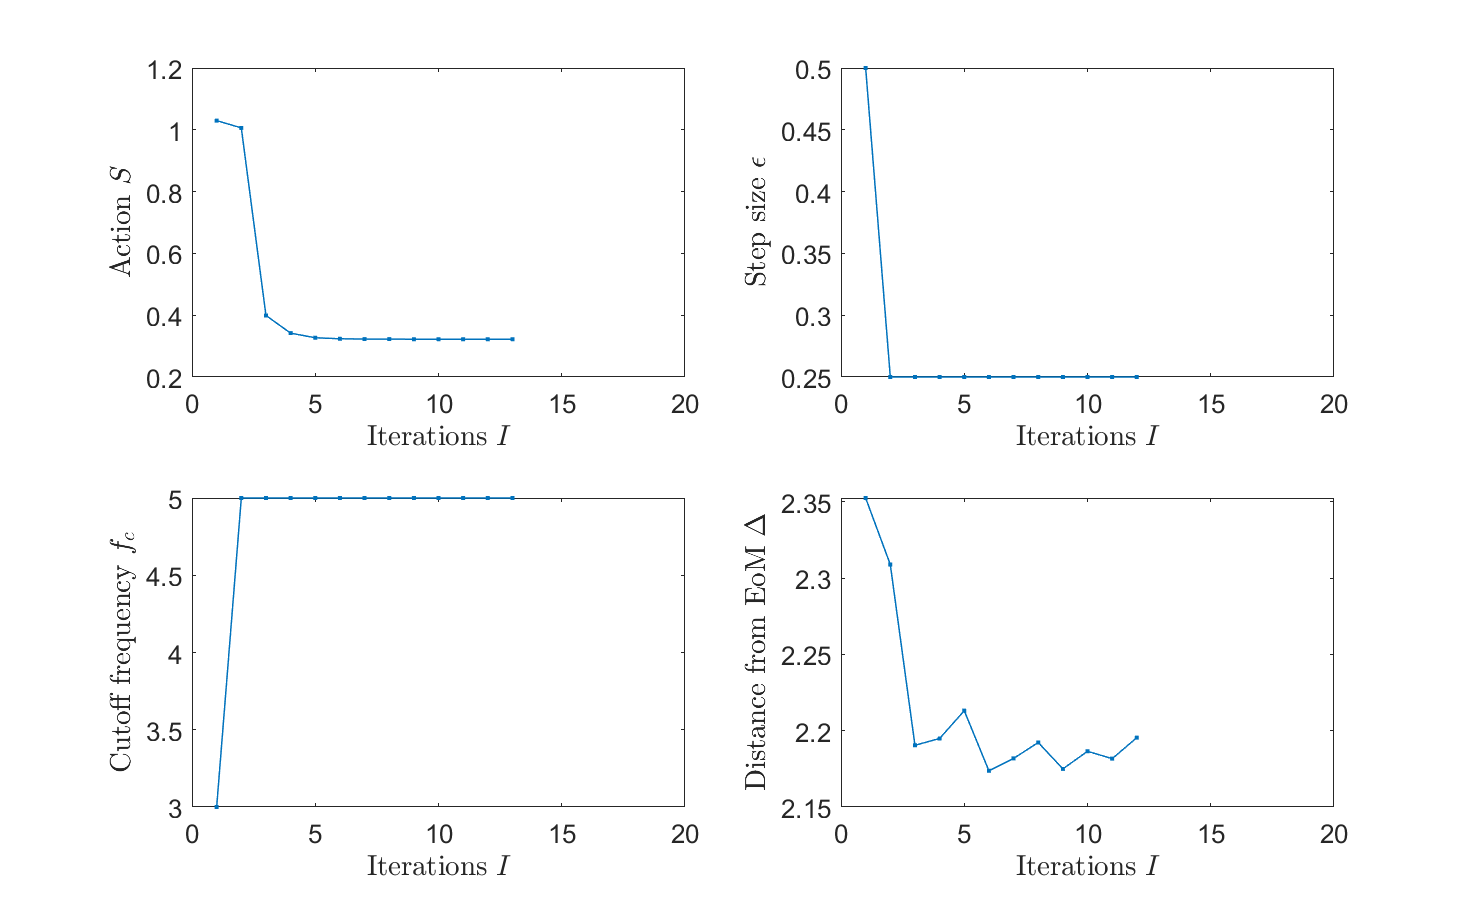


%Action
figure()
subplot(2,2,1)
plot(S_arr,'.-','LineWidth',0.75)
ylabel('Action $S$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

%title(plotnam + ': Descent summary')

%epsilon-step size
subplot(2,2,2)
plot(eps_arr,'.-','LineWidth',0.75)
ylabel('Step size $\epsilon$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

%title(plotnam + ': Descent summary')

%cutoff frequency bin
subplot(2,2,3)
plot(f0_arr,'.-','LineWidth',0.75)
ylabel('Cutoff frequency $f_c$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;


%Ham EoM distance frequency bin
subplot(2,2,4)
plot(a_arr,'.-','LineWidth',0.75)
ylabel('Distance from EoM $\Delta$','interpreter','latex','FontSize',20)
xlabel('Iterations $I$','interpreter','latex','FontSize',20)
%grid on
xlim([0 ceil(size(S_arr,1)/10)*10])
ax=gca;
ax.FontSize = 13;

x0=0.1;
y0=0.1;
width=26;
height=16;
set(gcf,'position',[x0,y0,width,height])
set(gcf,'units','centimeters','position',[x0,y0,width,height])

save_plot_name = save_plot_name_root + '_action_eps_freq_delta.png';

Unrecognized function or variable 'save_plot_name_root'.

saveas(gcf,save_plot_name)